## FIRST original data analysis

### Import data

Import FIRST dataset from FIRST.bin file. 

DataFileFolder = '../data/';
AnalysisContext = 16; % 10 for DR10; 16 for DR16
FIRSTori = readtable([DataFileFolder,'FIRST.bin'],'FileType','text');

FIRST = FIRSTori;
if(AnalysisContext == 10)
    TODELETE = (FIRST.SDSS_Matches )<=0;
    FIRST(TODELETE,:)=[];   
end
Lines = height(FIRST);
FIRST.id = (1:Lines)';
FIRST.RA = (FIRST.RAH + FIRST.RAm/60 + FIRST.RAs/60/60)/24*360;
FIRST.DEC = FIRST.DecH + FIRST.DecM/60 + FIRST.DecS/60/60;

Import SDSS data

SDSSori = readtable([DataFileFolder,'FIRST_DR', ...
    num2str(AnalysisContext),'_wondering_2.csv'],'FileType','text');
SDSS = SDSSori;

#### Display catalog

the **type** of sources. 

- 3: galaxy

- 6: star

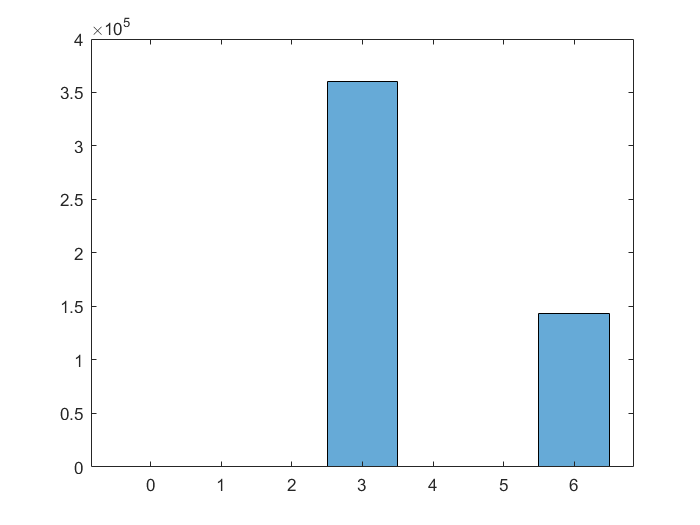

histogram(SDSS.type)

SDSS(SDSS.type~=3,:)=[];

**clean**

1: clean

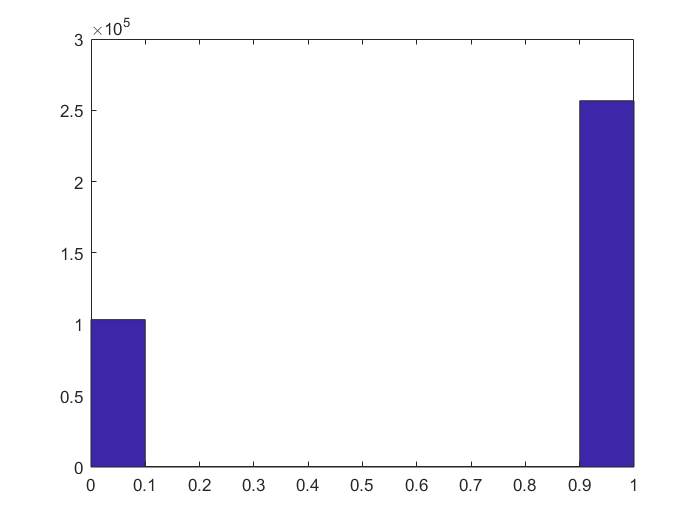

hist(SDSS.clean)

**concentration **

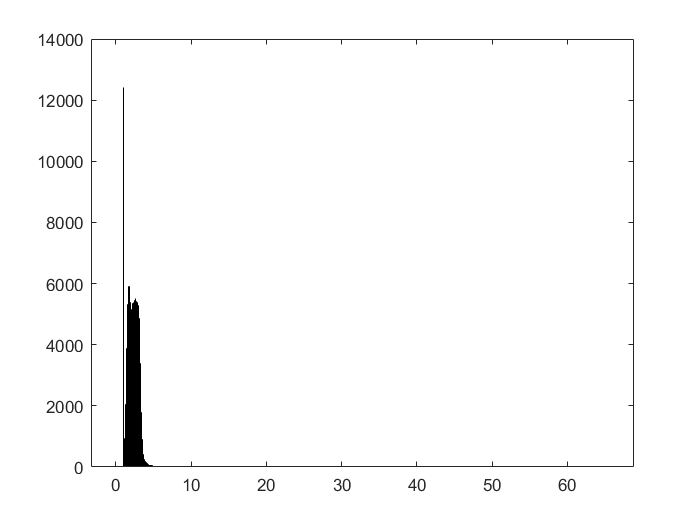

figure
h= histogram(SDSS.concentration);

- Small c : exponential profile and fits the profile of a disc galaxy

- large c: approximated by a de Vaucouleurs profile which is often used to model the light distribution of an elliptical galaxy

ConValve = 2;


SDSS.gPA = zeros(height(SDSS),1);
SDSS.gPA(SDSS.concentration < ConValve) = ...
    SDSS.gPAexp(SDSS.concentration < ConValve);
SDSS.gPA(SDSS.concentration >= ConValve) = ...
    SDSS.gPAde(SDSS.concentration >= ConValve);

SDSS.iPA = zeros(height(SDSS),1);
SDSS.iPA(SDSS.concentration < ConValve) = ...
    SDSS.iPAexp(SDSS.concentration < ConValve);
SDSS.iPA(SDSS.concentration >= ConValve) = ...
    SDSS.iPAde(SDSS.concentration >= ConValve);

SDSS.uPA = zeros(height(SDSS),1);
SDSS.uPA(SDSS.concentration < ConValve) = ...
    SDSS.uPAexp(SDSS.concentration < ConValve);
SDSS.uPA(SDSS.concentration >= ConValve) = ...
    SDSS.uPAde(SDSS.concentration >= ConValve);

SDSS.PA = zeros(height(SDSS),1);
SDSS.PA = zeros(height(SDSS),1);
SDSS.PA(SDSS.concentration < ConValve) = ...
    SDSS.PAexp(SDSS.concentration < ConValve);
SDSS.PA(SDSS.concentration >= ConValve) = ...
    SDSS.PAde(SDSS.concentration >= ConValve);




SDSS.BA = zeros(height(SDSS),1);
SDSS.BA(SDSS.concentration < ConValve) = ...
    SDSS.expAB_r(SDSS.concentration < ConValve);
SDSS.BA(SDSS.concentration >= ConValve) = ...
    SDSS.deVAB_r(SDSS.concentration >= ConValve);


I wanna to figure out the relation between concentration and fit mode difference(de Vaucouleurs or exponential). This could be done later.

#### *Exclude*

*Exclude galaxies with r>18, b/a>0.8 in either SDSS or FIRST and a<2 arcsec in FIRST. *

SDSS(SDSS.r>18 | SDSS.BA>0.8 | ...
    SDSS.PA<-360 | SDSS.gPA<-360 | ...
    SDSS.uPA<-360 | SDSS.iPA<-360,:) = [];
FIRST = FIRST(SDSS.id, :);
TODELETE = ((FIRST.Min ./ FIRST.Maj)>0.8 )|( FIRST.Maj<2)|( FIRST.P_S_>0.15);
SDSS(ismember(SDSS.id,FIRST.id(TODELETE)),:) = [];
FIRST(TODELETE,:) = [];

## Match SDSS with FIRST

#### check SDSS catalog 

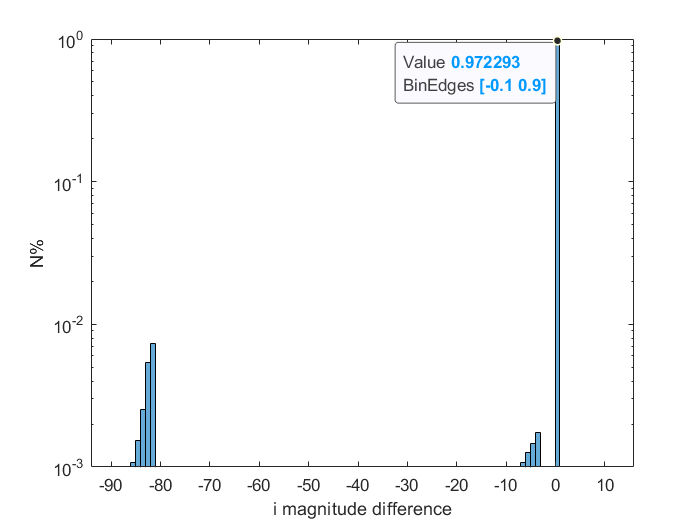

Lines = height(FIRST);
% SDSS(SDSS.id> 1e5,:)=[];
SDSS.i(SDSS.i < 0)=-1;
% MatchRows = intersect(SDSS.id,FIRST.id);
histogram(SDSS.i-FIRST.i,100,"Normalization",'probability')
set(gca,'yscale','log')
ylabel('N%')
ax = gca;
ylim([1e-3 1])
xlabel('i magnitude difference')
chart = ax.Children(1);
datatip(chart,0.17,0.8938);

writetable(FIRST,[DataFileFolder,'FIRST_merge.csv']);
writetable(SDSS,[DataFileFolder,'SDSS_merge.csv']);
clear